**1. Control System Tuner**

open_system('GrindingRobot')

Setup the paramter for Grinding System

Ts = 0.1;
Tf = 10;

run('../config.m')

Tune the system using Control System Tuner

controlSystemTuner("ControlSystemTunerSession")

After executing the script, navigate to the "Tuning" tab and select "Tune" to begin the tuning process

% blockPath = 'GrindingRobot/PID Controller';
% 
% % Get parameters
% Kp = get_param(blockPath, 'P');
% Ki = get_param(blockPath, 'I');
% 
% fprintf('PI Gains:\nKp = %s\nKi = %s', Kp, Ki);

Kp_CST = 1.25; % this is taken from the tuner session
Ki_CST = 1.25e-07;

**2. RL tuner **

Load the Simulink model that integrates the reinforcement learning environment, configure the observation and action space dimensions, and set a fixed random seed to ensure consistent results across runs.

mdl = 'rlgrindingsystemPIDTune';
open_system(mdl)

[env,obsInfo,actInfo] = localCreatePIDEnv(mdl);
numObs = prod(obsInfo.Dimension);
numAct = prod(actInfo.Dimension);

rng(0)

Set up the actor neural network

initialGain = single([1e-3 2]);
% initialGain = single([1.25 1.25e-7]);

actorNet = [
    featureInputLayer(numObs)
    fullyConnectedPILayer(initialGain,'ActOutLyr')
    ];

actorNet = dlnetwork(actorNet);

actor = rlContinuousDeterministicActor(actorNet,obsInfo,actInfo);

Define critic networks

criticNet = localCreateCriticNetwork(numObs,numAct);

critic1 = rlQValueFunction(initialize(criticNet), ...
    obsInfo,actInfo,...
    ObservationInputNames='stateInLyr', ...
    ActionInputNames='actionInLyr');

critic2 = rlQValueFunction(initialize(criticNet), ...
    obsInfo,actInfo,...
    ObservationInputNames='stateInLyr', ...
    ActionInputNames='actionInLyr');

critic = [critic1 critic2];

Define the training options

actorOpts = rlOptimizerOptions( ...
    LearnRate=1e-3, ...
    GradientThreshold=1);

criticOpts = rlOptimizerOptions( ...
    LearnRate=1e-3, ...
    GradientThreshold=1);

agentOpts = rlTD3AgentOptions(...
    SampleTime=Ts,...
    MiniBatchSize=128, ...
    ExperienceBufferLength=1e6,...
    ActorOptimizerOptions=actorOpts,...
    CriticOptimizerOptions=criticOpts);

agentOpts.TargetPolicySmoothModel.StandardDeviation = sqrt(0.1);

agent = rlTD3Agent(actor,critic,agentOpts);

Train the RL agent

maxepisodes = 1000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    MaxEpisodes=maxepisodes, ...
    MaxStepsPerEpisode=maxsteps, ...
    ScoreAveragingWindowLength=100, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=-355);

% doTraining = false;
doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the example.
    % load("GrindingSystem.mat","agent")
end

Evaluation

simOpts = rlSimulationOptions(MaxSteps=maxsteps);
experiences = sim(env,agent,simOpts);

actor = getActor(agent);
parameters = getLearnableParameters(actor);

Ki = abs(parameters{1}(1))

Ki = single
0.8198

Kp = abs(parameters{1}(2))

Kp = single
1.0633

mdlTest = 'GrindingRobot';
open_system(mdlTest); 
set_param([mdlTest '/PID Controller'],'P',num2str(Kp))
set_param([mdlTest '/PID Controller'],'I',num2str(Ki))
sim(mdlTest)

rlStep = simout;
rlCost = cost;
rlStabilityMargin = localStabilityAnalysis(mdlTest);

set_param([mdlTest '/PID Controller'],'P',num2str(Kp_CST))
set_param([mdlTest '/PID Controller'],'I',num2str(Ki_CST))
sim(mdlTest)
cstStep = simout;
cstCost = cost;
cstStabilityMargin = localStabilityAnalysis(mdlTest);

Compare 2 approaches

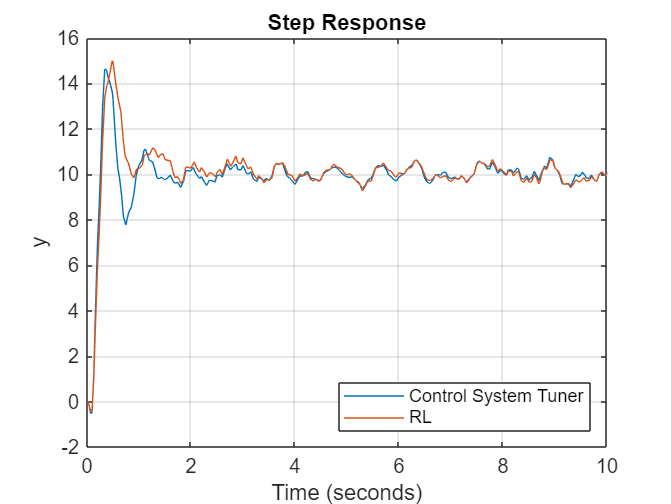

figure
plot(cstStep)
hold on
plot(rlStep)
grid on
legend('Control System Tuner','RL',Location="southeast")
title('Step Response')

rlStepInfo = stepinfo(rlStep.Data,rlStep.Time);
cstStepInfo = stepinfo(cstStep.Data,cstStep.Time);
stepInfoTable = struct2table([cstStepInfo rlStepInfo]);
stepInfoTable = removevars(stepInfoTable,{'SettlingMin', ...
    'TransientTime','SettlingMax','Undershoot','PeakTime'});
stepInfoTable.Properties.RowNames = {'CST','RL'};
stepInfoTable

stepInfoTable = 2×4 table
           RiseTime    SettlingTime    Overshoot     Peak 
           ________    ____________    _________    ______

    CST     0.1153         9.833        44.947       14.63
    RL     0.13392        9.8272         49.02      14.993


stabilityMarginTable = struct2table( ...
    [cstStabilityMargin rlStabilityMargin]);
stabilityMarginTable = removevars(stabilityMarginTable,{...
    'GMFrequency','PMFrequency','DelayMargin','DMFrequency'});
stabilityMarginTable.Properties.RowNames = {'CST','RL'};
stabilityMarginTable

stabilityMarginTable = 2×3 table
           GainMargin     PhaseMargin    Stable
           ___________    ___________    ______

    CST    0    1.6618      37.377       true  
    RL     0    1.9404      38.081       true  


rlCumulativeCost  = sum(rlCost.Data)

rlCumulativeCost = -295.2960

cstCumulativeCost = sum(cstCost.Data)

cstCumulativeCost = -275.5743